### Lavet af: Noah Rahbek Bigum Hansen

### Dato: 4. december 2024

### Studienummer: 202405538

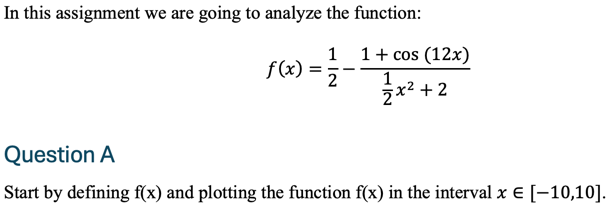

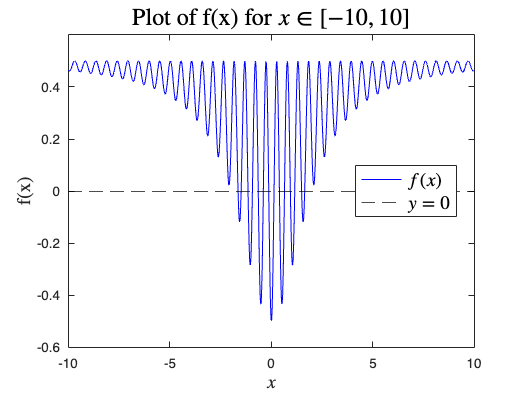

%define function
f = @(x) 1/2 - (1 + cos(12*x)) ./ (1/2 * x.^2 + 2);

%define interval for x
x = linspace(-10, 10, 1000);

%evaluate function and save results to variable for easier debugging
y = f(x);

%initialize plot
figure;
grid on;

%plot function
plot(x, y, "b");
hold on;

%make dashed black line at y = 0 to visualize where the function approximately has roots
yline(0, "k--")

%make labels for title, x- and y-axis using latex for better formatting
xlabel("$x$", "Interpreter", "latex", "FontSize", 14);
ylabel("f(x)", "Interpreter", "latex", "FontSize", 14);
title("Plot of f(x) for $x \in [-10, 10]$", "Interpreter", "latex", "FontSize", 18);

%define plot-intervals
xlim([-10, 10]);
ylim([-0.6, 0.6]);

%add legend for good measure
legend("$f(x)$", "$y = 0$", "Interpreter", "latex", "FontSize", 14, "Location", "best");
hold off;

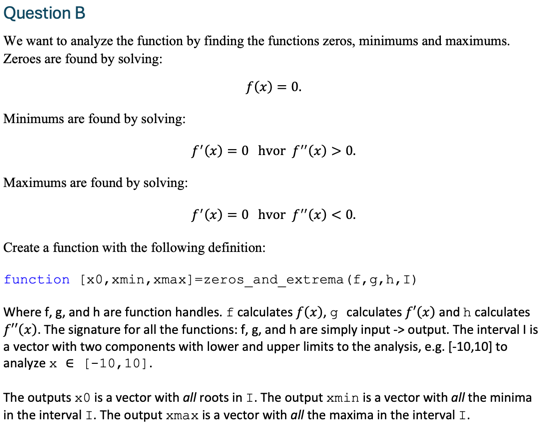

For this excercise Newtons method will *not* be applied to find the roots as Newtons method will be used later in the assignment (Question E) and this excercise permits me to use brute force. The following solution will therefore utilize both Matlabs built-in "diff"- and "fzero"-functionality. The function zeroz_and_extrema(f, g, h, I) is defined in the "functions"-section at the bottom of this script. In the code snippet below the function, f, from question A is analyzed with the zeroz_and_extrema function and the arrays containing the roots, minima and maxima are printed.

%define symbolic function to be able to use MatLabs built-in "diff"-functionality
syms x;
f_sym = 1/2 - (1 + cos(12*x)) / ((1/2)*x^2 + 2);

%find derivatives of f_sym with respect to x using "diff"
f_prime_sym = diff(f_sym, x);         %f'(x)
f_2prime_sym = diff(f_prime_sym, x);  %f''(x)

%convert the above symbolic functions to MatLab_functions to be able to run
%computations on them
f = matlabFunction(f_sym, "Vars", x);              %f(x)
g = matlabFunction(f_prime_sym, "Vars", x);        %f'(x)
h = matlabFunction(f_2prime_sym, "Vars", x);       %f''(x)

%define interval
I = [-10, 10];

%call the zeros_and_extrema-function
[x0, xmin, xmax] = zeros_and_extrema(f, g, h, I);

%print symbolic representation of function
disp("Analyzing the function:");

Analyzing the function:


disp(f_sym);

$$\frac{1}{2}-\frac{\cos\left(12\,x\right)+1}{\frac{x^{2}}{2}+2}$$


%print interval
fprintf("in the interval [%g, %g] gives the following:", I(1), I(2));

in the interval [-10, 10] gives the following:


%roots
if isempty(x0)
    fprintf("No roots found.");
else
    fprintf("%d roots:", length(x0));
    fprintf("%6s", "x"); %display "x" in a 6 charactes wide cell for centering
    fprintf("------------");
    for i = 1:length(x0)
        fprintf("%10.6f\n", x0(i));
    end
end

14 roots:

     x

------------

 -1.640222
 -1.488843
 -1.150016
 -0.934645
 -0.645794
 -0.395966
 -0.130545
  0.130545
  0.395966
  0.645794
  0.934645
  1.150016
  1.488843
  1.640222



%minima
if isempty(xmin)
    fprintf("No local minima found.");
else
    fprintf("%d local minima:", length(xmin));
    fprintf("%6s %14s", "x", "f(x)");
    fprintf("-------------------------");
    for i = 1:length(xmin)
        fprintf("%10.5f %12.5f\n", xmin(i), f(xmin(i)));
    end
end

39 local minima:

     x           f(x)

-------------------------

  -9.94569      0.46114
  -9.42196      0.45690
  -8.89821      0.45193
  -8.37444      0.44606
  -7.85066      0.43908
  -7.32686      0.43069
  -6.80303      0.42049
  -6.27917      0.40795
  -5.75528      0.39232
  -5.23136      0.37258
  -4.70739      0.34723
  -4.18339      0.31416
  -3.65935      0.27028
  -3.13530      0.21119
  -2.61129      0.13087
  -2.08746      0.02222
  -1.56406     -0.11950
  -1.04151     -0.28575
  -0.52022     -0.43625
   0.00000     -0.50000
   0.52022     -0.43625
   1.04151     -0.28575
   1.56406     -0.11950
   2.08746      0.02222
   2.61129      0.13087
   3.13530      0.21119
   3.65935      0.27028
   4.18339      0.31416
   4.70739      0.34723
   5.23136      0.37258
   5.75528      0.39232
   6.27917      0.40795
   6.80303      0.42049
   7.32686      0.43069
   7.85066      0.43908
   8.37444      0.44606
   8.89821      0.45193
   9.42196      0.45690
   9.94569      0.46114



%maxima
if isempty(xmax)
    fprintf("No local maxima found.");
else
    fprintf("and %d local maxima:", length(xmax));
    fprintf("%6s %14s", "x", "f(x)");
    fprintf("-------------------------");
    for i = 1:length(xmax)
        fprintf("%10.5f %12.5f\n", xmax(i), f(xmax(i)));
    end
end

and 38 local maxima:

     x           f(x)

-------------------------

  -9.68658      0.50000
  -9.16298      0.50000
  -8.63938      0.50000
  -8.11578      0.50000
  -7.59218      0.50000
  -7.06858      0.50000
  -6.54498      0.50000
  -6.02139      0.50000
  -5.49779      0.50000
  -4.97419      0.50000
  -4.45059      0.50000
  -3.92699      0.50000
  -3.40339      0.50000
  -2.87979      0.50000
  -2.35619      0.50000
  -1.83260      0.50000
  -1.30900      0.50000
  -0.78540      0.50000
  -0.26180      0.50000
   0.26180      0.50000
   0.78540      0.50000
   1.30900      0.50000
   1.83260      0.50000
   2.35619      0.50000
   2.87979      0.50000
   3.40339      0.50000
   3.92699      0.50000
   4.45059      0.50000
   4.97419      0.50000
   5.49779      0.50000
   6.02139      0.50000
   6.54498      0.50000
   7.06858      0.50000
   7.59218      0.50000
   8.11578      0.50000
   8.63938      0.50000
   9.16298      0.50000
   9.68658      0.50000


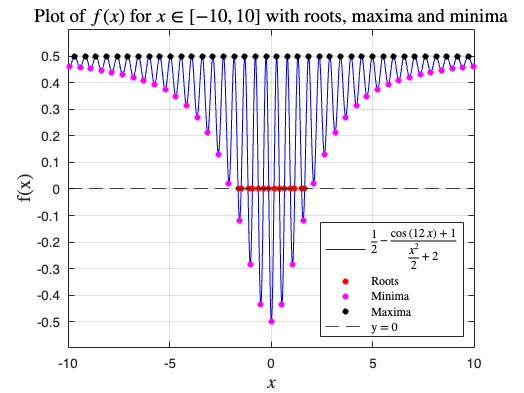

%all the following definitions are the same as was used for Question B
syms x;
f_sym = 1/2 - (1 + cos(12*x)) / ((1/2)*x^2 + 2);

%find derivatives of f_sym with respect to x using "diff"
f_prime_sym = diff(f_sym, x);         %f'(x)
f_2prime_sym = diff(f_prime_sym, x);  %f''(x)

%convert the above symbolic functions to MatLab_functions to be able to run
%computations on them
f = matlabFunction(f_sym, "Vars", x);              %f(x)
g = matlabFunction(f_prime_sym, "Vars", x);        %f'(x)
h = matlabFunction(f_2prime_sym, "Vars", x);       %f''(x)

%define interval
I = [-10, 10];

%call the zeros_and_extrema-function
[x0, xmin, xmax] = zeros_and_extrema(f, g, h, I);

%compute y-values for all the x-values the zeros_and_extrema function runs on
gridSize = 1000;
x_vals = linspace(I(1), I(2), gridSize);
y_vals = f(x_vals);

f_lat = ['$' latex(f_sym) '$']; %make f_sym into a latex-style string for prettier legend

%compute y-values for all roots, minima, and maxima at once for efficiency
y0 = f(x0);
ymin = f(xmin);
ymax = f(xmax);

%plot
figure;
plot(x_vals, y_vals, "b", "DisplayName", f_lat);  %plot of f(x)
hold on;

%mark roots as red dots if there are any
if ~isempty(x0)
    plot(x0, y0, "ro", "MarkerSize", 4, "MarkerFaceColor", "r" ,"DisplayName", "Roots");
end

%mark minima as magenta dots if there are any
if ~isempty(xmin)
    plot(xmin, ymin, "mo", "MarkerSize", 4, "MarkerFaceColor", "m" , "DisplayName", "Minima");
end

%mark maxima as black dots if there are any
if ~isempty(xmax)
    plot(xmax, ymax, "ko", "MarkerSize", 4, "MarkerFaceColor", "k" , "DisplayName", "Maxima");
end

%make dashed black line at y = 0
yline(0, "k--", "DisplayName", "y = 0");

%customize plot and use latex for rendering of text
grid on;
xlabel("$x$", "Interpreter", "latex", "FontSize", 14);
ylabel("f(x)", "Interpreter", "latex", "FontSize", 14);
title("Plot of $f(x)$ for $x \in [-10, 10]$ with roots, maxima and minima", "Interpreter", "latex", "FontSize", 14);

%define plotting-interval for y-values
ylim([min(y_vals)-0.1, max(y_vals)+0.1]);

%add legend
legend("show", "Location", "se", "Interpreter", "latex");
hold off;

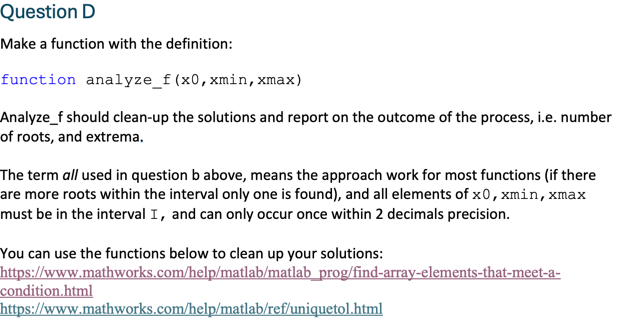

To clean up the solutions a function has been defined, which rounds all the values to 2 decimal places and removes duplicate points if there are any. 

analyze_f(x0, xmin, xmax); %call function using arrays from before

Cleaned results:

14 roots:
------------
  -1.64
  -1.49
  -1.15
  -0.93
  -0.65
  -0.40
  -0.13
  0.13
  0.40
  0.65
  0.93
  1.15
  1.49
  1.64

39 local minima:
------------
  -9.95
  -9.42
  -8.90
  -8.37
  -7.85
  -7.33
  -6.80
  -6.28
  -5.76
  -5.23
  -4.71
  -4.18
  -3.66
  -3.14
  -2.61
  -2.09
  -1.56
  -1.04
  -0.52
  0.00
  0.52
  1.04
  1.56
  2.09
  2.61
  3.14
  3.66
  4.18
  4.71
  5.23
  5.76
  6.28
  6.80
  7.33
  7.85
  8.37
  8.90
  9.42
  9.95

38 local maxima:
------------
  -9.69
  -9.16
  -8.64
  -8.12
  -7.59
  -7.07
  -6.54
  -6.02
  -5.50
  -4.97
  -4.45
  -3.93
  -3.40
  -2.88
  -2.36
  -1.83
  -1.31
  -0.79
  -0.26
  0.26
  0.79
  1.31
  1.83
  2.36
  2.88
  3.40
  3.93
  4.45
  4.97
  5.50
  6.02
  6.54
  7.07
  7.59
  8.12
  8.64
  9.16
  9.69


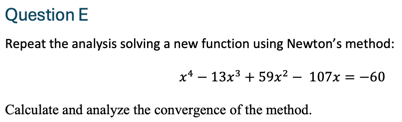

The following code will plot the given function to aid in the process of finding initial guesses for Newtons method

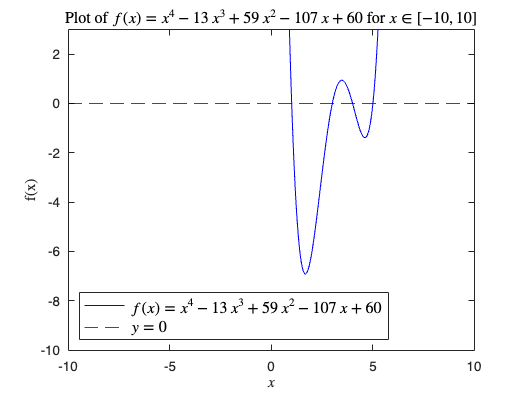

%define function, first derivative, and second derivative
syms x;
f_sym = x^4 - 13*x^3 + 59*x^2 - 107*x + 60; %f(x)
f_prime_sym = diff(f_sym, x);               %f'(x)
f_2prime_sym = diff(f_prime_sym, x);  %f''(x)

%convert the above symbolic expressions to MatLab functions
f = matlabFunction(f_sym, "Vars", x);
f_prime = matlabFunction(f_prime_sym, "Vars", x);
f_2prime = matlabFunction(f_2prime_sym, "Vars", x);

%define interval
I = [-10, 10];

%plot the function to get an idea about what the initial guesses for the roots
%and critical points should be
x_vals = linspace(I(1), I(2), 1000); %define x-values for plot
y_vals = f(x_vals);                  %define y-values for plot
f_latex = latex(f_sym);              %convert f(x) to LaTeX

%make plot
figure;
grid on;
plot(x_vals, y_vals, "b");
hold on;
yline(0, "k--")
xlabel("$x$", "Interpreter", "latex");
ylabel("f(x)", "Interpreter", "latex");
title(['Plot of $f(x) = ' f_latex '$ for $x \in [-10, 10]$'], ...
    "Interpreter", "latex", "FontSize", 12);
xlim([-10, 10]);
ylim([-10, 3]); 
legend(['$f(x) = ' f_latex '$'], "$y = 0$", ...
    "Interpreter", "latex", "FontSize", 12, "Location", "sw");
hold off;

Note: it has been visually checked that no critical points lie outside of the drawn plot. Also a polynomial of degree 4 will only have 3 critical points and 4 roots meaning all points of interest are plotted. 

Based on the plot it seems as though the roots are around x=0; x=2,5; x=3,75 and x=5,5; whilst the critical points are around x=1, x=3 and x=5.

In the following code the roots and extrema of the given equation are both found using a function called Newton, which implements Newton's method. The results are then cleaned up using the analyze_f-function from Question D. 

%parameters for Newton's Method
tol = 1e-6;                                   %tolerance
max_iter = 100;                               %maximum iterations
initial_guesses_roots = [0, 2.5, 3.75, 5.5];  %initial guesses for the roots
initial_guesses_crit = [1, 3, 4];             %initial guesses for the critical points


%the boxed code below can be de-commented to see the calculated exact roots
%and critical points

%_________________________________________________
%exact_roots = double(solve(f_sym == 0, x));
%disp("Symbolically calculated roots:");
%disp(exact_roots);

%exact_crit = vpa(solve(f_prime_sym == 0, x), 10);
%disp("Symbolically calculated critical points:");
%disp(exact_crit);
%-------------------------------------------------


%save exact values of roots and critical points to be able to calculate convergence rate
exact_roots = [1, 3, 4, 5];
exact_crit = [1.6736545366, 3.4690934444, 4.6072520188];

%initialize variables for root finding with Newton's method
roots = [];
iter_data_roots = [];
rates_root = cell(1, length(initial_guesses_roots)); %cell array so all convergence rates for a
                                                     %given root can be stored in the same place
x_n_sequence = cell(1, length(initial_guesses_roots)); %x_n sequence for convergence rate finding

%run loop over all initial guesses for roots
for i = 1:length(initial_guesses_roots)
    %run Newton's method for each guess
    [root, iter_data_root] = newton(f, f_prime, initial_guesses_roots(i), tol, max_iter);
    roots = [roots, root]; %store the found root

    %extract x_n from iter_data and save in array
    x_n_sequence = [iter_data_root.x_n];
    
    %compute convergence rate
    if length(x_n_sequence) >= 3
        %call rate function
        q = rate(x_n_sequence, exact_roots(i));
        rates_root{i} = q; %store rates for this specific root
    else
        fprintf("Not enough iterations to compute convergence rate for initial guess %.4f\", initial_guesses_roots(i));
        rates_root{i} = []; %mark as empty if not enough data
    end
end

%initialize variables for critical point finding with Newton's method
critical_points = [];
iter_data_crits = [];
rates_crit = cell(1, length(initial_guesses_crit));
x_n_sequences = cell(1, length(initial_guesses_crit));

%run loop for all initial guesses for critical points
for i = 1:length(initial_guesses_crit)
    %call Newton's method for each guess
    [crit, iter_data_crit] = newton(f_prime, f_2prime, initial_guesses_crit(i), tol, max_iter);
    critical_points = [critical_points, crit]; %store critical point

    %extract x_n from iteration data
    x_n_sequence = [iter_data_crit.x_n];

    %compute convergence rates
    if length(x_n_sequence) >= 3
        q = rate(x_n_sequence, exact_crit(i));
        rates_crit{i} = q; %store rates
    else
        fprintf("Not enough iterations to compute convergence rate for initial guess %.4f\n", initial_guesses_crit(i));
        rates_crit{i} = []; %mark as empty if insufficient data
    end
end

%determine if critical points are maxima or minima using the secon derivative
minima = critical_points(f_2prime(critical_points) > 0); %f'' > 0 => minima
maxima = critical_points(f_2prime(critical_points) < 0); %f'' < 0 => maxima

%analyze and clean results
analyze_f(roots, minima, maxima);

Cleaned results:

4 roots:
------------
  1.00
  3.00
  4.00
  5.00

2 local minima:
------------
  1.67
  4.61

1 local maxima:
------------
  3.47



%display the convergence rates for each root
for i = 1:length(rates_root)
    fprintf("Convergence rates for root %.4f (initial guess %.4f):\n", ...
        exact_roots(i), initial_guesses_roots(i));
    if ~isempty(rates_root{i}) %only display the convergence rates if there are any
        disp(rates_root{i});
    else
        fprintf("Not enough data to compute convergence rate.\n");
    end
end

Convergence rates for root 1.0000 (initial guess 0.0000):


    1.5083
    1.7367
    1.9304
    1.9949
    2.0114



Convergence rates for root 3.0000 (initial guess 2.5000):


    1.4969
    1.9318
    1.9973



Convergence rates for root 4.0000 (initial guess 3.7500):


    3.5082
    1.8572



Convergence rates for root 5.0000 (initial guess 5.5000):


    1.5659
    1.8025
    1.9626
    1.9985




%display the convergence rates for each critical point
disp("Convergence rates for critical points:");

Convergence rates for critical points:


for i = 1:length(rates_crit)
    fprintf("\nCritical point %.10f (initial guess %.4f):\n", ...
        exact_crit(i), initial_guesses_crit(i));

    %display convergence rates if there are any
    if ~isempty(rates_crit{i})
        fprintf("Convergence rates:\n");
        disp(rates_crit{i});
    else
        fprintf("Not enough data to compute convergence rate.\n");
    end
end


Critical point 1.6736545366 (initial guess 1.0000):


Convergence rates:


    1.6560
    1.8886
    1.9887
    1.3402




Critical point 3.4690934444 (initial guess 3.0000):


Convergence rates:


    1.6544
    2.0255




Critical point 4.6072520188 (initial guess 4.0000):


Convergence rates:


   -0.4084
    1.5577
    1.3893
    1.6103
    1.8566
    1.9820
    1.5435



Based on the calculatede convergence rates it is evident that the convergence rate of the implementation of Newton's method is right around 2 – that is quadratic convergence. The calculated convergence rates seems to approach 2 although the last calculated value is in a couple of cases quite a bit lower than two, but after extensive testing this has been deemed to be a numerical artefact that can happen if the the method is beginning to approximate the root better than the "exact" value of the root that is passed to the rate-function.

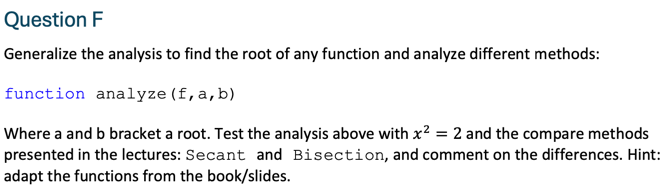

To be able to find all the roots in the given interval a helper function called find_root_guesses will be used. This helper function divides the interval into a lot of smaller subintervals and identifies which of these subintervals that contain roots. A function will be defined for each method (secant, bisection and the previously made Newton-function) and these functions will then be called for each subinterval containing a root. Also a helper plotting-function, which will plot the given function and mark all critical points and roots has been defined and this will be called at the end of the main analyze-function.  A print_iteration_data function has also been implemented, which allows the user to see the iteration data for each method by setting the ok flag in the code snippet below to true. A plotting helper function that allows the user to see the graph of the function with roots, maxima and minima marked has also been created.


Finding Roots.

Finding Critical Points.

Finding maxima and minima.

Convergence Rates for Roots:

Bisection (Roots):

Root/Critical Point 1:
Not enough data to compute convergence rates.

Root/Critical Point 2:
Not enough data to compute convergence rates.

Secant (Roots):

Root/Critical Point 1:
Median Convergence Rate: 1.7305

Root/Critical Point 2:
Median Convergence Rate: 1.4086

Newton (Roots):

Root/Critical Point 1:
Median Convergence Rate: 2.0015

Root/Critical Point 2:
Median Convergence Rate: 2.0015

Convergence Rates for Critical Points:

Bisection (Critical Points):

Root/Critical Point 1:
Not enough data to compute convergence rates.

Secant (Critical Points):

Root/Critical Point 1:
Not enough data to compute convergence rates.

Newton (Critical Points):

Root/Critical Point 1:
Not enough data to compute convergence rates.

Analyzing results.
Results:
      Method             Roots          Minima      Maxima</

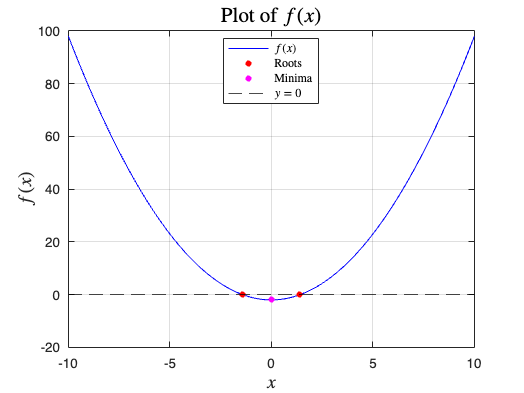

global ok; %make ok a global variable so the analyze(f, a, b) function
%can see it without passing it as an input. Note: It would be more efficient 
%to pass ok as an input to the function, but this approach has been chosen
%to not diverge from the function handle given in the assignment.

ok = false; %set this flag to true for printing of iteration data


%analysis of function from Question F
syms x
f = x^2 - 2;

a = -10;
b = 10;

analyze(f, a, b);

The above code correctly identifies the roots and the minima of the given function sing all three methods. The critical point is found by all methods rather in the first one or two iterations due to the way the methods each interpret the results from the find_root_guesses function and no convergence rate can therefore be calculated for these. For the roots however the convergence rates are pretty much what is to be expected. 

Newton's method has a convergence rate very close to the expected value of 2 for both roots which aligns with the expected quadratic convergence.

The secant method has a convergence rate between 1,5 and 1,7 depending on which of the roots we are looking at, once again this aligns with the expected superlinear convergence.

For the bisection method the root is in all the cases found too quickly (due to "lucky" guesses" produced by the find_root_intervals-function) to be able to calculate the convergence rate, however it is expected to have a convergence rate around 1. 

To show that the function is generalized an analysis of the function from Question E has also been made


Finding Roots.

Finding Critical Points.

Finding maxima and minima.

Convergence Rates for Roots:

Bisection (Roots):

Root/Critical Point 1:
Not enough data to compute convergence rates.

Root/Critical Point 2:
Not enough data to compute convergence rates.

Root/Critical Point 3:
Not enough data to compute convergence rates.

Root/Critical Point 4:
Not enough data to compute convergence rates.

Secant (Roots):

Root/Critical Point 1:
Median Convergence Rate: 1.7733

Root/Critical Point 2:
Median Convergence Rate: 1.8621

Root/Critical Point 3:
Median Convergence Rate: 1.4390

Root/Critical Point 4:
Median Convergence Rate: 1.4129

Newton (Roots):

Root/Critical Point 1:
Median Convergence Rate: 2.0005

Root/Critical Point 2:
Median Convergence Rate: 2.0030

Root/Critical Point 3:
Median Convergence Rate: 1.9908

Root/Critical Point 4:
Median Convergence Rate: 2.0309

Convergence Rates for Critical Points:

Bisection (Critical Points):

Root/Critical Point 1:
Not enough data to compu

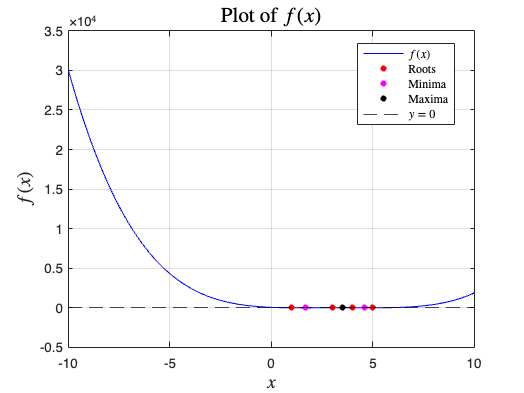

%analysis of function from Question E
f_sym = x^4 - 13*x^3 + 59*x^2 - 107*x + 60;

%Note: The interval has been skewed slightly to avoid bisection finding the
%roots to quickly to be able to calculate a convergence rate
a = -10;
b = 10;

analyze(f_sym, a, b);

Once again the bisection method finds the roots and critical points too quickly for a convergence rate to be calculated (once again this is due to "lucky" guesses made by the find_root_guesses-function). The expected convergence rate for the bisection method is linear (1).

For the secant method method the convergene rate is around 1,5, which fits nicely into the expected result of superlinear convergence. 

For the Newton method the convergence rates are all rather close to 2, which also fits the expected result of quadratic convergence. 

## Functions

%function for Question B
function [x0, xmin, xmax] = zeros_and_extrema(f, g, h, I)
    %inputs:
    %  f = f(x)
    %  g = f'(x)
    %  h = f''(x)
    %  I = Interval [a, b] for function to find zeros and extrema in
    %outputs:
    %  x0   = Roots of f(x) in I
    %  xmin = Minima of f(x) in I
    %  xmax = Maxima of f(x) in I

    arguments                    %validate input parameters
        f (1,1) function_handle  %f must be a scalar function
        g (1,1) function_handle  %g must be a scalar function
        h (1,1) function_handle  %h must be a scalar function
        I (1,2) {mustBeNumeric}  %I must be a 1x2 vector of numbers
    end
    %note that f, g, and h is restricted to be scalar function_handles (1,1) to
    % avoid the user inputting an array of function handles.

    %define a fine grid of x-values as fzero only gives one output per
    %interval given, thus we need to break the larger interval I into a lot
    %of smaller intervals to ensure we find all zeros and extremas
    gridSize = 1000; %define size of grid in variable to make modifications easier
    xgrid = linspace(I(1), I(2), gridSize);
    
    %find zeros using fzero in the helper function find_zeros
    x0 = find_zeros(f, xgrid);

    %find critical points using the helper function
    xcrit = find_zeros(g, xgrid);


    %determine if each of the found critical points are minimums or maximums

    %initialize output variables
    xmin = [];
    xmax = [];

    %run a for loop over all the previously found critical points
    for i = 1:length(xcrit)
        %evaluate h = f''(x) at the critical point
        hval = h(xcrit(i));
        if hval > 0 %check if critical point is a minimum
            xmin = [xmin; xcrit(i)]; %if critical point is local minimum update
                                     % array containing minimas
        elseif hval < 0
            xmax = [xmax; xcrit(i)]; %else if critical point is a local maximum update
                                     % array containing maximas
        end
    end
end




%define helper function for zeros_and_extrema to avoid redundany in the main function
function roots = find_zeros(func, xgrid)
    arguments                       %validate input parameters
        func (1,1) function_handle  %func must be a scalar function
        xgrid {mustBeNumeric}       %xgrid must only consist of numbers
    end

    roots = []; %initialize variable to store output-values
    for i = 1:length(xgrid) - 1 %run a for loop over all the smaller intervals in xgrid to find out which
                                %intervals contains a zero (this is similar to the bisection method)
        if func(xgrid(i)) * func(xgrid(i+1)) < 0
            %if there is a root in the interval the root is found by fzero
            root = fzero(func, [xgrid(i), xgrid(i+1)]);
            %store each root in x0 by updating x0 for each found root and
            %appending the new root to the entire array of previously found roots
            roots = [roots; root];
        end
    end
end




%function for question D
function analyze_f(x0, xmin, xmax)
    arguments                %validate input parameters
        x0 {mustBeNumeric}   %x0 must be a numeric scalar
        xmin {mustBeNumeric} %xmin must be a numeric scalar
        xmax {mustBeNumeric} %xmax must be a numeric scalar
    end

    %define the interval I
    I = [-10, 10];

    %remove duplicate values (unique to 2 decimal places)
    x0 = uniquetol(x0, 1e-2);
    xmin = uniquetol(xmin, 1e-2);
    xmax = uniquetol(xmax, 1e-2);

    %round all the arrays to 2 decimal places
    x0 = round(x0, 2);
    xmin = round(xmin, 2);
    xmax = round(xmax, 2);


    %ensure all values are in the interval – this makes use of two logical
    %arrays (in paranthesis). These are combined with & meaning the result
    %is filtered away if the found root or extrema isn't in the interval
    x0 = x0(x0 >= I(1) & x0 <= I(2));
    xmin = xmin(xmin >= I(1) & xmin <= I(2));
    xmax = xmax(xmax >= I(1) & xmax <= I(2));

    %print the cleaned results
    fprintf("Cleaned results:\n");
    fprintf("============\n");

    %roots
    if isempty(x0)
       fprintf("No roots found in the interval.\n");
    else
       fprintf("\n%d roots:\n", length(x0));
       fprintf("------------\n");
       fprintf("  %.2f\n", x0);
    end


    %minima
    if isempty(xmin)
        fprintf("No minima found in the interval.\n");
    else
    fprintf("\n%d local minima:\n", length(xmin));
    fprintf("------------\n");
    fprintf("  %.2f\n", xmin);
    end


    %maxima
    if isempty(xmax)
        fprintf("No maxima found in the interval.\n");
    else
        fprintf("\n%d local maxima:\n", length(xmax));
        fprintf("------------\n");
        fprintf("  %.2f\n", xmax);
    end
end




%function for question E
function [root, iter_data] = newton(f, df, x0, tol, max_iter)
%implementation of newtons method that finds a root and stores iteration
%data.
    arguments
        f (1,1) function_handle        %f must be a scalar function
        df (1,1) function_handle       %df must be a scalar function
        x0 {mustBeNumeric}             %x0 must only contain numbers
        tol (1,1) {mustBeNumeric}      %tolerance must be scalar number
        max_iter (1,1) {mustBeNumeric} %max_iter must be scalar number
    end

    %initialize variables
    iter_data = [];         %iteration data
    x_n = x0;               %initial guess
    iter = 0;               %iteration counter

    %run the method for a maximum of max_iter iterations
    while iter < max_iter
        iter = iter + 1; %update iteration counter

        %evaluate function and derivative
        f_xn = f(x_n);
        df_xn = df(x_n);

        %check if the derivative is too small (to avoid overshooting)
        if abs(df_xn) < 1e-6
            warning("Derivative too small at x = %.8f.", x_n);
            break;
        end

        %compute next guess using Newton's update formula
        x_n_new = x_n - f_xn / df_xn;

        %record iteration data
        iter_data = [iter_data; struct("iter", iter, "x_n", x_n, "f_xn", f_xn)];

        %check for convergence
        if abs(f_xn) < tol
            root = x_n_new; %converged to root
            return;
        end

        x_n = x_n_new; %update guess
    end

    %if max iterations reached without convergence, issue a warning
    if iter == max_iter
        warning("No convergence after %d iterations.", max_iter);
    end

    %assign the final estimate as the root
    root = x_n;

    %append the final iteration data
    iter_data = [iter_data; struct("iter", iter, "x_n", x_n, "f_xn", f_xn)];
end


%convergence-rate-function
function q = rate(x, x_exact)
    %calculate errors at each iteration
    e = abs(x - x_exact);

    %initialize vector to store convergence rates
    q = zeros(length(e) - 2, 1);

    %compute convergence rates using equation from book
    for n = 2:(length(e) - 1)
            %compute rates
            q(n - 1) = log(e(n + 1) / e(n)) / log(e(n) / e(n - 1));
    end

    %replace extreme rates with NaN to avoid a good guess skewing the
    %convergence rates
    q(abs(q) > 10 | isnan(q)) = NaN;
end



%main-function for Question F
function analyze(f_sym, a, b)
    %this function will analyze a given symbolic function and find its
    %roots, minma and maxima within the given interval. On top of this the
    %results will be printed in a nicely formatted way and with an
    %accompanying plot. If the ok flag is true the iteration data will
    %also be printed

    arguments %validate input parameters
        f_sym (1,1) sym          %f must be a scalar symbolic function
        a (1,1) {mustBeNumeric}  %a must be a scalar number
        b (1,1) {mustBeNumeric}  %b must be a scalar number
    end

    global ok; %declare ok as a global inside the function so the function can access it

    %convert symbolic function to a MatLab function
    syms x;
    f = matlabFunction(f_sym, "Vars", x);

    %compute derivatives using the symbolic function
    df_sym = diff(f_sym, x);    %f'(x)
    d2f_sym = diff(df_sym, x);  %f''(x)
 
    %convert derivatives to MatLab functions
    df = matlabFunction(df_sym, "Vars", x);
    d2f = matlabFunction(d2f_sym, "Vars", x);

    %tolerance and maximum iterations
    tol = 1e-8;
    max_iter = 100;


    % 1. Find all roots in [a, b]
    %===================================

    % 1.1 Divide interval into subintervals and check if each subinterval
    %contains a root
    fprintf("\nFinding Roots.\n"); %print message to let user know
                                   % function has started execution

    subintervals = linspace(a, b, 500); %divide [a,b] into 99 subintervals
    root_intervals = find_root_guesses(f, subintervals); %check if each subinterval contains
                                                         %a root with the helper
                                                         %function find_root_guesses

    % 1.2 Use Bisection method to find roots
    [roots_bisection, iter_data_bisection] = find_all_roots_bisection(f, root_intervals, tol, max_iter);

    % 1.3 Use Secant method to find roots
    [roots_secant, iter_data_secant] = find_all_roots_secant(f, root_intervals, tol, max_iter);

    % 1.4 Use Newton's method to find roots
    [roots_newton, iter_data_newton] = find_all_roots_newton(f, df, root_intervals, tol, max_iter);


    % 2. Find all critical points in [a, b]
    %=======================================

    % 2.1 Divide interval into subintervals and check if each subinterval
    %contains a root
    fprintf("\nFinding Critical Points.\n"); %update user on progress

    crit_intervals = find_root_guesses(df, subintervals); %check if each subinterval contains
                                                          %a critical point by running
                                                          %find_root_guesses on the
                                                          %derivative of f, df.

    % 2.2 Use Bisection method to find critical points
    [crit_bisection, iter_data_crit_bisection] = find_all_roots_bisection(df, crit_intervals, tol, max_iter);

    % 2.3 Use Secant method to find critical points
    [crit_secant, iter_data_crit_secant] = find_all_roots_secant(df, crit_intervals, tol, max_iter);

    % 2.4 Use Newton's method to find critical points
    [crit_newton, iter_data_crit_newton] = find_all_roots_newton(df, d2f, crit_intervals, tol, max_iter);


    % 3. Classify critical points as either maxima or minima
    %========================================================
    fprintf("\nFinding maxima and minima.\n"); %update user on progress

    % 3.1 Minima and maxima for the bisection method
    minima_bisection = crit_bisection(d2f(crit_bisection) > 0); %f'' > 0 => minimum
    maxima_bisection = crit_bisection(d2f(crit_bisection) < 0); %f'' < 0 => maximum

    % 3.2 Minima and maxima for the secant method
    minima_secant = crit_secant(d2f(crit_secant) > 0); %f'' > 0 => minimum
    maxima_secant = crit_secant(d2f(crit_secant) < 0); %f'' < 0 => maximum

    % 3.3 Minima and maxima for the newton method
    minima_newton = crit_newton(d2f(crit_newton) > 0); %f'' > 0 => minimum
    maxima_newton = crit_newton(d2f(crit_newton) < 0); %f'' < 0 => maximum


    % 4. Print Convergence rate
    %===========================
    fprintf("\nFinding convergence rates.\n"); %update user on progress


    % 4.0 Define exact values
    roots_exact = double(solve(f_sym == 0, x));
    crit_exact = double(solve(df_sym == 0, x));

    % 4.1 convergence rate for roots
    fprintf("\nConvergence Rates for Roots:\n");
    compute_and_print_rates("Bisection (Roots)", iter_data_bisection, roots_exact);
    compute_and_print_rates("Secant (Roots)", iter_data_secant, roots_exact);
    compute_and_print_rates("Newton (Roots)", iter_data_newton, roots_exact);

    % 4.2 Convergence rate for critical points
    fprintf("\nConvergence Rates for Critical Points:\n");
    compute_and_print_rates("Bisection (Critical Points)", iter_data_crit_bisection, crit_exact);
    compute_and_print_rates("Secant (Critical Points)", iter_data_crit_secant, crit_exact);
    compute_and_print_rates("Newton (Critical Points)", iter_data_crit_newton, crit_exact);


    % 5. Analyze results
    %====================
    fprintf("\nAnalyzing results.\n"); %update user on progress

    % 5.1 round each result from the bisection method to 2 digits and ensure
    %they're unique
    roots_bisection = unique(round(roots_bisection, 2));
    minima_bisection = unique(round(minima_bisection, 2));
    maxima_bisection = unique(round(maxima_bisection, 2));

    % 5.2 round each result from the secant method to 2 digits and ensure
    %they're unique
    roots_secant = unique(round(roots_secant, 2));
    minima_secant = unique(round(minima_secant, 2));
    maxima_secant = unique(round(maxima_secant, 2));

    % 5.3 round each result from the newton method to 2 digits and ensure
    %they're unique
    roots_newton = unique(round(roots_newton, 2));
    minima_newton = unique(round(minima_newton, 2));
    maxima_newton = unique(round(maxima_newton, 2));


    % 6. Print analyzed results in a table
    %===========================
    %define method names
    Method = ["Bisection"; "Secant"; "Newton"];
    
    %define output data for each method
    roots_all = {roots_bisection, roots_secant, roots_newton};
    minima_all = {minima_bisection, minima_secant, minima_newton};
    maxima_all = {maxima_bisection, maxima_secant, maxima_newton};
    
    %initialize cell arrays to store formatted results
    Roots = cell(3, 1);
    Minima = cell(3, 1);
    Maxima = cell(3, 1);
    
    %format roots (replace empty cells with "N/A") – to do this we also
    %need to convert the rest of the valus to strings as MatLab throws an
    %error if the data types are mismatched
    for i = 1:3
        if isempty(roots_all{i})
            Roots{i} = "N/A";
        else
            Roots{i} = join(string(roots_all{i}), ", ");
        end
    end
    
    %format minima
    for i = 1:3
        if isempty(minima_all{i})
            Minima{i} = "N/A";
        else
            Minima{i} = join(string(minima_all{i}), ", ");
        end
    end
    
    %format maxima
    for i = 1:3
        if isempty(maxima_all{i})
            Maxima{i} = "N/A";
        else
            Maxima{i} = join(string(maxima_all{i}), ", ");
        end
    end
    
    %create and display the table
    ResultsTable = table(Method, Roots, Minima, Maxima);
    disp("Results:");
    disp(ResultsTable);

    %print iteration data if required
    if ok
        fprintf("\nIteration Data:\n");
        print_iteration_data("Bisection (Roots)", iter_data_bisection);
        print_iteration_data("Secant (Roots)", iter_data_secant);
        print_iteration_data("Newton (Roots)", iter_data_newton);
        print_iteration_data("Bisection (Critical Points)", iter_data_crit_bisection);
        print_iteration_data("Secant (Critical Points)", iter_data_crit_secant);
        print_iteration_data("Newton (Critical Points)", iter_data_crit_newton);
    end

    % 7. Plot function with highlighted roots, minima, and maxima
    %=============================================================
    %call plot_analysis helper-function to plot and format the results
    %nicely
    plot_analysis(f, a, b, roots_bisection, minima_bisection, maxima_bisection);
end




%helper function for analyze(f_sym, a, b) that finds subintervals containing roots
function root_intervals = find_root_guesses(f, subintervals)
    %the main idea behind this function is to check if a given subinterval
    %contains a root by checking if the sign of the function changes in the
    %interval

    arguments                         %validate input parameters
        f (1,1) function_handle       %f must be a scalar function
        subintervals {mustBeNumeric}  %subintervals must only contain numbers
    end

    %initialize variable to store the subintervals that contain a root
    root_intervals = [];
    for i = 1:length(subintervals) - 1 %loop over all given intervals
        if f(subintervals(i)) * f(subintervals(i + 1)) < 0 %if sign changes in interval a root must be contained
            %append the given subinterval to the previously found ones
            root_intervals = [root_intervals; subintervals(i), subintervals(i + 1)];
        end
    end
end




%helper function for analyze(f, a, b) that implements the bisection_method
function [root, iter_data] = bisection_method(f, a, b, tol, max_iter)
    %each time the function is called a single root is found

    arguments                            %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        a (1,1) {mustBeNumeric}          %a must be a scalar number
        b (1,1) {mustBeNumeric}          %b must be a scalar number
        tol (1,1) {mustBeNumeric}        %tol must be a scalar number
        max_iter (1,1) {mustBeNumeric}   %max_iter must be a scalar number
    end

    iter_data = []; %initialize variable to store iteration data
    iterations = 0; %initialize variable to store amount of iterations

    %run loop until convergence is reached
    while iterations < max_iter
        c = (a + b) / 2; %find midpoint of interval

        %calculate function value at leftmost point in interval, rightmost
        %point in interval and at midpoint
        f_a = f(a);
        f_c = f(c);

        %update iteration counter
        iterations = iterations + 1; 

        %record iteration data
        iter_data = [iter_data; struct("iter", iterations + 1, "a", a, "b", b, "c", c, "f_c", f_c)];

        if f_c < tol %if midpoint is 0 it is a root
            root = c; %store c as root if it is a root
            return;
        elseif f_a * f_c < 0
            b = c; %root lies in [a, c]
        else
            a = c; %root lies in [c, b]
        end
    end

    root = (a + b) / 2; %final approximation

    %store final iteration data
    iter_data = [iter_data; struct("iter", iterations + 1, "a", a, "b", b, "c", root, "f_c", f(root))];
end




%helper function for analyze(f, a, b) that finds all roots in the interval
%using the bisection_method-function defined above
function [roots, iter_data] = find_all_roots_bisection(f, intervals, tol, max_iter)

    arguments                            %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        intervals {mustBeNumeric}        %intervals must only contain numbers
        tol (1,1) {mustBeNumeric}        %tol must be a scalar number
        max_iter (1,1) {mustBeNumeric}   %max_iter must be a scalar number
    end

    roots = [];     %initialize variable to store roots
    iter_data = {}; %initialize variable to store iteration data

    for i = 1:size(intervals, 1) %run loop for each given interval
        
        %use bisection method on each pass of the loop
        [r, iter] = bisection_method(f, intervals(i, 1), intervals(i, 2), tol, max_iter);

        roots = [roots; r];      %store found roots
        iter_data{i} = iter;     %store iteration data
    end
end




%helper function for analyze(f, a, b) that implements the secant_method
function [root, iter_data] = secant_method(f, x0, x1, tol, max_iter)
    %each time the function is called a single root is found

    arguments                            %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        x0 (1,1) {mustBeNumeric}         %x0 must be a scalar number
        x1 (1,1) {mustBeNumeric}         %x1 must be a scalar number
        tol (1,1) {mustBeNumeric}        %tol must be a scalar number
        max_iter (1,1) {mustBeNumeric}   %max_iter must be a scalar number
    end    
    
    iter_data = []; %initialize variable for iteration data
    iterations = 0; %initialize variable to store amount of iterations

    %run the method until convergence or the iteration threshold is hit
    while abs(x1-x0) > tol && iterations < max_iter
        f_x0 = f(x0); %evaluate f at leftmost point of interval
        f_x1 = f(x1); %evaluate f at rightmost point of interval

        %handle division by zero by printing error
        if abs(f_x1 - f_x0) < eps %eps is precision of the variable type "double"
            error("Secant method failed: Division by zero.");
        end

        %compute next point
        x2 = x1 - f_x1 * (x1 - x0) / (f_x1 - f_x0);

        %record iteration data
        iter_data = [iter_data; struct("iter", iterations + 1, "x0", x0, "x1", x1, "x2", x2, "f_x2", f(x2))];

        %update evaluation points
        x0 = x1;
        x1 = x2;
        iterations = iterations +1; %update iteration counter
    end

    %print warning if convergence hasn't happened within iteration limit
    if iterations == max_iter
        warning("Secant method did not converge within the maximum number of iterations.");
    end

    root = x1; %final estimate of root
end




%helper function for analyze(f, a, b) that finds all roots in the interval
%using the secant_method-function defined above
function [roots, iter_data] = find_all_roots_secant(f, intervals, tol, max_iter)

    arguments                            %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        intervals {mustBeNumeric}        %intervals must only contain numbers
        tol (1,1) {mustBeNumeric}        %tol must be a scalar number
        max_iter (1,1) {mustBeNumeric}   %max_iter must be a scalar number
    end

    roots = [];     %initialize variable to store roots
    iter_data = {}; %initialize variable to store iteration data

    for i = 1:size(intervals, 1) %run loop for each given interval
        
        %use secant method on each pass of the loop
        [r, iter] = secant_method(f, intervals(i, 1), intervals(i, 2), tol, max_iter);

        roots = [roots; r];      %store found roots
        iter_data{i} = iter; %store iteration data
    end
end




%helper function for analyze(f, a, b) that finds all roots in the interval
%using the newton_method-function defined in Question D
function [roots, iter_data] = find_all_roots_newton(f, df, intervals, tol, max_iter)

    arguments                            %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        df (1,1) function_handle         %df must be a scalar function
        intervals {mustBeNumeric}        %intervals must only contain numbers
        tol (1,1) {mustBeNumeric}        %tol must be a scalar number
        max_iter (1,1) {mustBeNumeric}   %max_iter must be a scalar number
    end

    roots = [];     %initialize variable to store roots
    iter_data = {}; %initialize variable to store iteration data

    for i = 1:size(intervals, 1) %run loop for each given interval

        %set initial guess as midpoint of interval
        initial_guess = (intervals(i,1) + intervals(i,2)) / 2;

        %use newton method on each pass of the loop
        [r, iter] = newton(f, df, initial_guess, tol, max_iter);

        roots = [roots; r];      %store found roots
        iter_data{i} = iter;     %store iteration data
    end
end




%helper-function for the rates-function to print convergence rates
function compute_and_print_rates(method_name, iter_data, exact_values)
    %compute and print the median convergence rate for roots or critical points
    fprintf("\n%s:\n", method_name);

    for j = 1:length(iter_data)
        fprintf("\nRoot/Critical Point %d:\n", j);

        %extract the sequence of iterations based on method
        if contains(method_name, 'Bisection', 'IgnoreCase', true)
            %use the midpoint 'c' for Bisection method
            x_n_sequence = [iter_data{j}.c];
        elseif contains(method_name, 'Secant', 'IgnoreCase', true)
            %use the 'x2' of the final iteration for Secant method
            x_n_sequence = [iter_data{j}.x2];
        elseif contains(method_name, 'Newton', 'IgnoreCase', true)
            %use the final guess 'x_n' for Newton's method
            x_n_sequence = [iter_data{j}.x_n];
        else
            error("Unrecognized method: %s", method_name);
        end

        %match computed root with the closest exact root to make sure the
        %convergence rate is calculated based on the correct root
        distances = abs(exact_values - x_n_sequence(end));
        [~, closest_index] = min(distances);   %find index of closest exact root
        x_exact = exact_values(closest_index); %assign the closest exact root

        %compute convergence rates
        if length(x_n_sequence) >= 3
            q = rate(x_n_sequence, x_exact);
            %compute and print the median convergence rate (use median to
            %avoid overloading the user with a different convergence
            %rate for each step)
            median_rate = mean(q, 'omitnan'); %omit NaN values in the median calculation
                                              %(these are made, when the rates function
                                              %calculates an unrealistic value due to
                                              %a "lucky" or "unlucky" guess
            fprintf("Median Convergence Rate: %.4f\n", median_rate);
        else
            fprintf("Not enough data to compute convergence rates.\n");
        end
    end
end




%helper function for analyze(f, a, b) that plots the function and the found
%maxima and minima
function plot_analysis(f, a, b, roots, minima, maxima)

    arguments %validate input parameters
        f (1,1) function_handle          %f must be a scalar function
        a (1,1) {mustBeNumeric}          %a must be a scalar numbers
        b (1,1) {mustBeNumeric}          %b must be a scalar numbers
        roots {mustBeNumeric}            %roots must only contain numbers
        minima {mustBeNumeric}           %minima must only contain numbers
        maxima {mustBeNumeric}           %maxima must only contain numbers
    end

    %generate values for plotting
    x_vals = linspace(a, b, 1000);
    y_vals = f(x_vals);

    %plot
    figure;
    plot(x_vals, y_vals, "b", "DisplayName", "$f(x)$");
    hold on
    
    %mark roots as red dots if there are any
    if ~isempty(roots)
        plot(roots, f(roots), "ro", "MarkerSize", 4, "MarkerFaceColor", "r" ,"DisplayName", "Roots");
    end
    
    %mark minima as magenta dots if there are any
    if ~isempty(minima)
        plot(minima, f(minima), "mo", "MarkerSize", 4, "MarkerFaceColor", "m" , "DisplayName", "Minima");
    end
    
    %mark maxima as black dots if there are any
    if ~isempty(maxima)
        plot(maxima, f(maxima), "ko", "MarkerSize", 4, "MarkerFaceColor", "k" , "DisplayName", "Maxima");
    end
    
    %customize plot
    xlabel("$x$", "Interpreter", "latex", "FontSize", 14);
    ylabel("$f(x)$", "Interpreter", "latex", "FontSize", 14);
    title("Plot of $f(x)$", "Interpreter", "latex", "FontSize", 16);
    legend("show", "Interpreter", "latex", "Location", "best");
    grid on;

    %mark y = 0 line
    yline(0, "k--", "DisplayName", "$y = 0$");

    hold off;
end



%helper function for analyze(f, a, b) that allows the user to print the
%iteration data if the print glaf is set to true
function print_iteration_data(method_name, iter_data)
    %print iteration for a given root finding algorithm

    %print header
    fprintf("Iteration data for the \n%s method:\n", method_name);
    
    for j = 1:length(iter_data) %loop through each root's iteration data
        fprintf("\n Root %d:\n", j); %subheader

        %determine fields to print based on method
        if contains(method_name, 'Bisection', 'IgnoreCase', true)
            %bisection Method
            fprintf("%6s %12s %12s %12s %12s\n", "Iter", "a", "b", "c", "f(c)");
            fprintf("----------------------------------------------------------\n");
            for k = 1:length(iter_data{j})
                data = iter_data{j}(k); %extract iteration data for iteration k of root j
                fprintf("%6d %12.6f %12.6f %12.6f %12.6f\n", data.iter, data.a, data.b, data.c, data.f_c);
            end

        elseif contains(method_name, 'Secant', 'IgnoreCase', true)
            %secant Method
            fprintf("%6s %12s %12s %12s %12s\n", "Iter", "x0", "x1", "x2", "f(x2)");
            fprintf("----------------------------------------------------------\n");
            for k = 1:length(iter_data{j})
                data = iter_data{j}(k); %extract iteration data for iteration k of root j
                fprintf("%6d %12.6f %12.6f %12.6f %12.6f\n", data.iter, data.x0, data.x1, data.x2, data.f_x2);
            end

        elseif contains(method_name, 'Newton', 'IgnoreCase', true)
            %newton Method
            fprintf("%6s %12s %12s\n", "Iter", "x_n", "f(x_n)");
            fprintf("-------------------------------\n");
            for k = 1:length(iter_data{j})
                data = iter_data{j}(k); %extract iteration data for iteration k of root j
                fprintf("%6d %12.6f %12.6f\n", data.iter, data.x_n, data.f_xn);
            end

        else
            %handle unknown methods
            fprintf("Unknown method type: %s\n", method_name);
        end
    end
end
